#  Main Script

## Testing Dynamic Model

% get ground truth and measurements from .txt files
clear
[ground_truth, imu_meas, n_timesteps, dt] = process('dataset9_davis');


% compute true measurements
%pseudo_Q = diag(ones(7,1)*0.01);
%[true_M, noisy_Z] = createMeasurements(ground_truth, pseudo_Q);

% initialize variables and initial state
[covIMU]  = IMUNoisesCovariances(dt);
init_state = ground_truth(:,1);
post_state = ground_truth(:,2);
postpost_state = ground_truth(:,3);
init_meas = imu_meas(2:end,1);
[muNom, muErr, sigma] = initialize(init_state, post_state, postpost_state, init_meas);

% loop
muNomTotal = zeros(19,n_timesteps);
muNomTotal(:,1) = muNom;
ACCEL = zeros(3, n_timesteps);
for i = 2:n_timesteps
    u = imu_meas(2:end,i);
    [muNom_bar, muErr_bar, sigma_bar, accel] = predict(muNom, ...
        muErr, sigma, u, covIMU, dt);
    sigma = sigma_bar;
    muNom = muNom_bar;
    muNomTotal(:,i) = muNom_bar;
    ACCEL(:,i) = accel;
end
%[muNom_bar, muErr_bar, sigma_bar] = predict(muNom, muErr, sigma, imu_meas, covIMU, dt, mode)

% Dynamic Trajectory plot
figure;
hold on;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Dynamic Particle Trajectory');
axis equal;
view(3);

% Plot the trajectory dynamically
trajectory = plot3(NaN, NaN, NaN, 'b', 'LineWidth', 1.5); % Trajectory line
particle = plot3(NaN, NaN, NaN, 'ro', 'MarkerFaceColor', 'r'); % Particle
x = muNomTotal(3,:);
y = muNomTotal(1,:);
z = muNomTotal(2,:);
for i = 1:n_timesteps
    % Update the trajectory and particle
    set(trajectory, 'XData', x(1:i), 'YData', y(1:i), 'ZData', z(1:i)); % Trajectory
    set(particle, 'XData', x(i), 'YData', y(i), 'ZData', z(i)); % Particle
    
    % Pause for animation
    pause(dt);
end


% Static Trajectory Plot
% Plot both trajectories -> first 2 seconds

figure;
hold on;
grid on;
n_sec = 10;
n_inst = round(n_sec/dt);

x1 = ground_truth(2,1:n_inst);
y1 = ground_truth(3,1:n_inst);
z1 = ground_truth(4,1:n_inst);

x2 = muNomTotal(1,1:n_inst);
y2 = muNomTotal(2,1:n_inst);
z2 = muNomTotal(3,1:n_inst);

% Plot the first trajectory
plot3(x1, y1, z1, 'b', 'LineWidth', 1.5); % Blue line

% Plot the second trajectory
plot3(x2, y2, z2, 'r--', 'LineWidth', 1.5); % Red dashed line

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Trajectories');

% Add legend
legend('True', 'Sim');

% Ensure equal scaling for axes and set the view
%axis equal;
view(3); % 3D view

## Testing with own-made dataset

Run the previous section or load

clear
close all
clc

muNomTotal = load("muNomTotal_dt0.01.mat"); %dt = 0.01s and we should use 1st 10 seconds
muNomTotal = muNomTotal.muNomTotal;
groundtruth_sim = muNomTotal([1:3, 7:10],:);


Initialize stuff

pseudo_Q = diag(1.*ones(1,7)); % cov. matrix from which we'll extract noise to add to measurements
mode = 1;
pseudo_R = diag(1.*ones(1,6)); % cov. matrix from which we'll extract noise to add to IMU meas.
R = [1*eye(3), 0.5.*eye(3), 0.1.*eye(3), 0.1.*eye(3)];% process covariance matrix (3x12)
Q = diag(1.*ones(1,7)); % measurement covariance matrix (7x7)

Run Kalman Filter with the simulated ground truth

clc

muNomInitial = muNomTotal(:,1);
muErrInitial = zeros(18,1);
sigmaInitial = eye(18);
lambda_M = 0.05; %threshold on likelihood
outlierSpecs.on = false; % there are no outliers in the observations
outlierSpecs.rate = 50; % x% of observations are outliers
[muNomTotal, muErrTotal, sigmaTotal, M, dt] = EKF('dataset9_davis', pseudo_Q, mode, pseudo_R, ...
    R, Q, groundtruth_sim, muNomInitial, muErrInitial, sigmaInitial, lambda_M, outlierSpecs);

Error Plot: Positions

subplot(3,1,1)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(1,:)-muNomTotal(1,:))
title('X Error')
subplot(3,1,2)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(2,:)-muNomTotal(2,:))
title('Y Error')
subplot(3,1,3)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(3,:)-muNomTotal(3,:))
title('Z Error')

Error Plot: Quaternions

subplot(2,2,1)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(4,:)-muNomTotal(7,:))
title('qw Error')
subplot(2,2,2)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(5,:)-muNomTotal(8,:))
title('qx Error')
subplot(2,2,3)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(6,:)-muNomTotal(9,:))
title('qy Error')
subplot(2,2,4)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth_sim(7,:)-muNomTotal(10,:))
title('qz Error')


Display Mean Absolute Errors

error_x = groundtruth_sim(1,:)-muNomTotal(1,:);
fprintf('The ME for the x position is %0.4g', mean(error_x))
fprintf('The MAE for the x position is %0.4g', mean(abs(error_x)))
error_y = groundtruth_sim(2,:)-muNomTotal(2,:);
fprintf('The ME for the y position is %0.4g', mean(error_y))
fprintf('The MAE for the y position is %0.4g', mean(abs(error_y)))
error_z = groundtruth_sim(3,:)-muNomTotal(3,:);
fprintf('The ME for the z position is %0.4g', mean(error_z))
fprintf('The MAE for the z position is %0.4g', mean(abs(error_z)))

error_qw = groundtruth_sim(4,:)-muNomTotal(7,:);
fprintf('The ME for qw %0.4g', mean(error_qw))
fprintf('The MAE for qw %0.4g', mean(abs(error_qw)))
error_qx = groundtruth_sim(5,:)-muNomTotal(8,:);
fprintf('The ME for qx %0.4g', mean(error_qx))
fprintf('The MAE for qx %0.4g', mean(abs(error_qx)))
error_qy = groundtruth_sim(6,:)-muNomTotal(9,:);
fprintf('The ME for qy %0.4g', mean(error_qy))
fprintf('The MAE for qy %0.4g', mean(abs(error_qy)))
error_qz = groundtruth_sim(7,:)-muNomTotal(10,:);
fprintf('The ME for qz %0.4g', mean(error_qz))
fprintf('The MAE for qz %0.4g', mean(abs(error_qz)))


Trajectory Plot

% Static Trajectory Plot
% Plot both trajectories -> first 2 seconds

figure;
hold on;
grid on;
n_sec = 10;
n_inst = round(n_sec/dt);

x1 = groundtruth_sim(1,:);
y1 = groundtruth_sim(2,:);
z1 = groundtruth_sim(3,:);

x2 = muNomTotal(1,:);
y2 = muNomTotal(2,:);
z2 = muNomTotal(3,:);

x_m = M(1,:);
y_m = M(2,:);
z_m = M(3,:);

% Plot the first trajectory
plot3(x1, y1, z1, 'b', 'LineWidth', 1.5); % Blue line

% Plot the second trajectory
plot3(x2, y2, z2, 'r--', 'LineWidth', 1.5); % Red dashed line

plot3(x_m, y_m, z_m, 'o','LineWidth', 3)

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Trajectories');

% Add legend
legend('Ground-Truth', 'Simulation', 'Landmarks');

% Ensure equal scaling for axes and set the view
%axis equal;
view(3); % 3D view

## Testing Indoor Dataset

Initialize stuff

clear
close all
clc

mode = 2;
pseudo_R = diag(0*ones(1,6)); % cov. matrix from which we'll extract noise to add to IMU meas.
R = [0.0005.*eye(3), 0.001.*eye(3), 0.001.*eye(3), 0.001.*eye(3)];% process covariance matrix (3x12)
pseudo_Q = diag(0.0001.*ones(1,7)); % cov. matrix from which we'll extract noise to add to measurements
Q = diag(0.001.*ones(1,7)); % measurement covariance matrix (7x7)


Run Kalman Filter

groundtruth_sim = NaN;
muNomInitial = NaN;
muErrInitial = 0.001*ones(18,1);
sigmaInitial = eye(18);
%sigmaInitial([4:6,11:16], [4:6,11:16]) = 3.*sigmaInitial([4:6,11:16], [4:6,11:16]);
lambda_M = 0; %threshold on likelihood
outlierSpecs.on = false; % there are no outliers in the observations
outlierSpecs.rate = 50; % x% of observations are outliers
[muNomTotal, muErrTotal, sigmaTotal, M, dt, groundtruth] = EKF('dataset9_davis', pseudo_Q, mode, pseudo_R, ...
    R, Q, groundtruth_sim, muNomInitial, muErrInitial, sigmaInitial, lambda_M, outlierSpecs);

100 %

groundtruth = groundtruth(2:end,:);

Error Plot: Positions

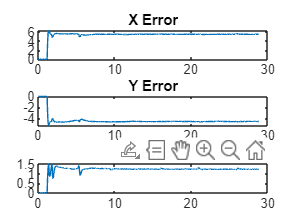

subplot(3,1,1)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(1,:)-muNomTotal(1,:))
title('X Error')
subplot(3,1,2)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(2,:)-muNomTotal(2,:))
title('Y Error')
subplot(3,1,3)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(3,:)-muNomTotal(3,:))
title('Z Error')

Error Plot: Quaternions

subplot(2,2,1)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(4,:)-muNomTotal(7,:))
title('qw Error')
subplot(2,2,2)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(5,:)-muNomTotal(8,:))
title('qx Error')
subplot(2,2,3)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(6,:)-muNomTotal(9,:))
title('qy Error')
subplot(2,2,4)
plot(0:dt:dt*(size(muNomTotal,2)-1), groundtruth(7,:)-muNomTotal(10,:))
title('qz Error')


Display Mean Absolute Errors

error_x = groundtruth(1,:)-muNomTotal(1,:);
fprintf('The ME for the x position is %0.4g', mean(error_x))
fprintf('The MAE for the x position is %0.4g', mean(abs(error_x)))
error_y = groundtruth(2,:)-muNomTotal(2,:);
fprintf('The ME for the y position is %0.4g', mean(error_y))
fprintf('The MAE for the y position is %0.4g', mean(abs(error_y)))
error_z = groundtruth(3,:)-muNomTotal(3,:);
fprintf('The ME for the z position is %0.4g', mean(error_z))
fprintf('The MAE for the z position is %0.4g', mean(abs(error_z)))

error_qw = groundtruth(4,:)-muNomTotal(7,:);
fprintf('The ME for qw %0.4g', mean(error_qw))
fprintf('The MAE for qw %0.4g', mean(abs(error_qw)))
error_qx = groundtruth(5,:)-muNomTotal(8,:);
fprintf('The ME for qx %0.4g', mean(error_qx))
fprintf('The MAE for qx %0.4g', mean(abs(error_qx)))
error_qy = groundtruth(6,:)-muNomTotal(9,:);
fprintf('The ME for qy %0.4g', mean(error_qy))
fprintf('The MAE for qy %0.4g', mean(abs(error_qy)))
error_qz = groundtruth(7,:)-muNomTotal(10,:);
fprintf('The ME for qz %0.4g', mean(error_qz))
fprintf('The MAE for qz %0.4g', mean(abs(error_qz)))


Trajectory Plot

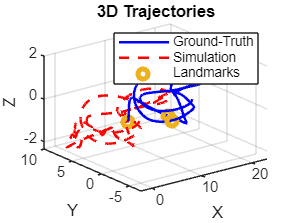

% Static Trajectory Plot
% Plot both trajectories -> first 2 seconds

figure;
hold on;
grid on;
n_sec = 28;
n_inst = round(n_sec/dt);

x1 = groundtruth(1, 1:n_inst);
y1 = groundtruth(2,1:n_inst);
z1 = groundtruth(3,1:n_inst);

x2 = muNomTotal(1,1:n_inst);
y2 = muNomTotal(2,1:n_inst);
z2 = muNomTotal(3,1:n_inst);

x_m = M(1,:);
y_m = M(2,:);
z_m = M(3,:);

% Plot the first trajectory
plot3(x1, y1, z1, 'b', 'LineWidth', 1.5); % Blue line

% Plot the second trajectory
plot3(x2, y2, z2, 'r--', 'LineWidth', 1.5); % Red dashed line

plot3(x_m, y_m, z_m, 'o','LineWidth', 3)

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Trajectories');

% Add legend
legend('Ground-Truth', 'Simulation', 'Landmarks');

% Ensure equal scaling for axes and set the view
%axis equal;
view(3); % 3D view